# Electricity Revenue

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

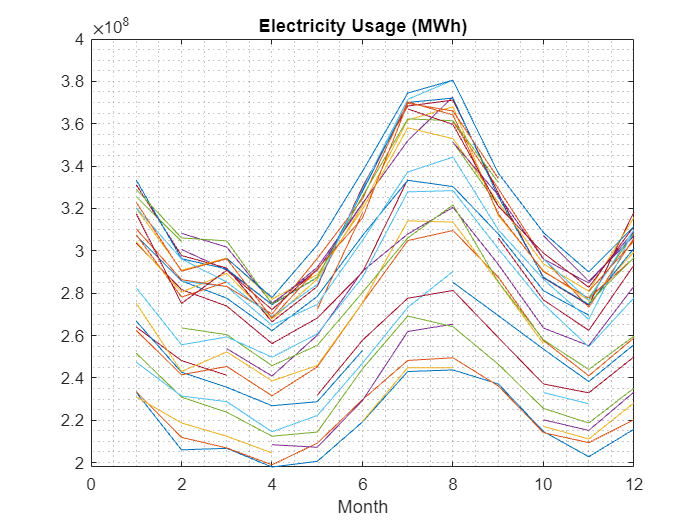

com = readmatrix("./data/electricity.xlsx", Sheet='com');
res = readmatrix("./data/electricity.xlsx", Sheet='res');
ind = readmatrix("./data/electricity.xlsx", Sheet='ind');
price = readmatrix("./data/electricity.xlsx", Sheet='price');

usage = com + res + ind;
price = price * 1000 / 100;

plot(usage)
grid minor
title("Electricity Usage (MWh)")
xlabel("Month")

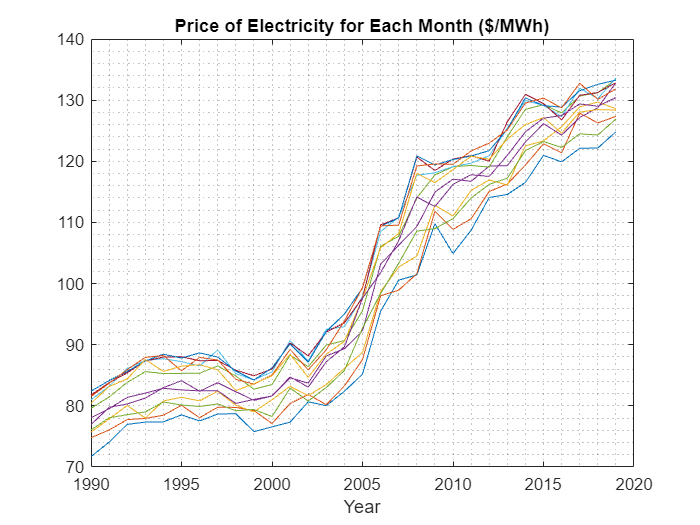

plot(1990:2019, price')
grid minor
title("Price of Electricity for Each Month ($/MWh)")
xlabel("Year")

## Task 1

Electricity revenue for each month from 1990-2019 can be calculated by multiplying each element of `price` by the respective element of `usage` using element-wise multiplication.

revenue = price .* usage

revenue = 1.0e+10 *

    1.6713    1.7293    1.7782    1.8212    1.9474    1.9423    2.0469    2.0985    2.0655    2.0859    2.1374       NaN    2.2792    2.4302    2.5311    2.6202    2.9043       NaN    3.3009       NaN    3.4745    3.6248    3.5400    3.6668       NaN    3.9798    3.8397    3.8778    4.2004    4.0298
    1.5408    1.6116    1.7005       NaN    1.8119    1.8536    1.9368    1.9360    1.9255    1.9254       NaN    2.1192    2.0924    2.2590    2.3794    2.4357    2.7484    2.9739    3.0931    3.1938    3.2421    3.2767    3.2948    3.3816    3.6800    3.7604    3.5950    3.5183       NaN    3.6975
    1.5649    1.6109    1.7010       NaN    1.8084    1.8619    1.9497    1.9410    1.9653    1.9933    2.0556    2.1665    2.1180    2.2867    2.3917    2.5319    2.8554    2.9876       NaN    3.1938    3.2412    3.3576    3.3113    3.4438    3.6971    3.7575    3.5834    3.7484    3.8446    3.8090
    1.5225    1.5870    1.6425    1.6940    1.7628    1.8047       NaN    1.

## Task 2

Those are some big numbers! Reporting these numbers in billions of dollars may be easier for many people to read and understand them.

You can round numbers in an array to `n` decimal places with the `round` function.

`round``(``M``,``n``)`

revBillion = round(revenue / 1e9, 3);

This code plots the prices for each year by month.

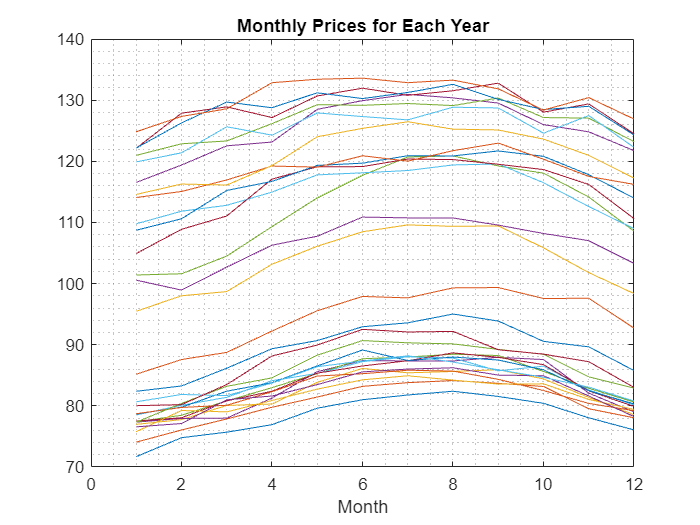

plot(price)
grid minor
title("Monthly Prices for Each Year")
xlabel("Month")

## Task 3

As you can see in the plot before Task 3, prices have fluctuated between months in a predictable way. So you will calculate *monthly* inflation rates. To do this, you need to divide the January 2019 price by the price in January 1990, the February 2019 price by February 1990, and so on.

priceInfl = price(:, end) ./ price(:, 1)

priceInfl =     1.7410
    1.7026
    1.6986
    1.7269
    1.6757
    1.6493
    1.6246
    1.6176
    1.6170
    1.5965
